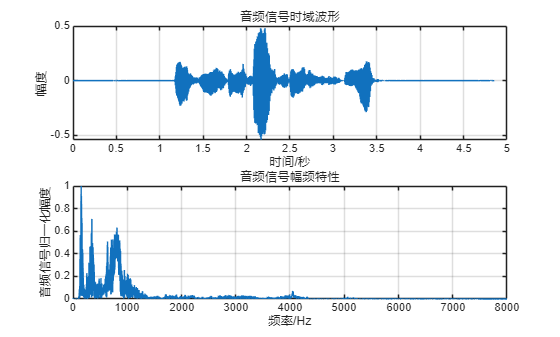

%% 要求：
% 利用audioread函数读取音频信号数据流及采样频率信息
% 绘制出音频信号的时域波形（横坐标单位为"秒"）及幅频图（纵坐标归一化，横坐标范围0~8000Hz）。

[y, fs] = audioread('dspx1.wav'); % fs为采样频率
n = length(y); % 采样点数

figure;
x = (0:length(y)-1)*(1/fs);
subplot(2, 1, 1);
plot(x, y);
xlabel('时间/秒');
ylabel('幅度');
title('音频信号时域波形');
grid on;

subplot(2, 1, 2);
Y = fft(y);
df = fs/n;
f = (0:1:n-1)*df;
plot(f, abs(Y)/max(abs(Y)));
grid on;
xlabel('频率/Hz');
ylabel('音频信号归一化幅度');
title('音频信号幅频特性');
axis([0, 8000, 0, 1]);